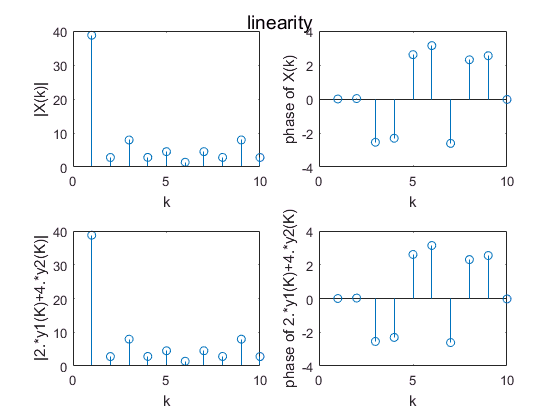

x1 = [0.59 ,0.95 ,0.95 ,0.59 ,0.00 ,0.59 ,0.95 ,0.95 ,0.59 ,0.00];
x2 = [0.16, 0.97, 0.96, 0.49, 0.80, 0.14, 0.42, 0.92, 0.79, 0.96];
x5=[zeros(1,5),x1];
x10=[zeros(1,3),x1];


figure
y1=fft(x1);
y2=fft(x2);
x3=2.*x1+4.*x2;
y3=fft(x3);
y4=2.*y1+4.*y2;
suptitle('linearity');
subplot(2,2,1);
stem(abs(y3));
xlabel('k');
ylabel('|X(k)|');
subplot(2,2,2);
stem(angle(y3));
xlabel('k');
ylabel('phase of X(k)');
subplot(2,2,3);
stem(abs(y4));
xlabel('k');
ylabel('|2.*y1(K)+4.*y2(K)|');
subplot(2,2,4);
stem(angle(y4));
xlabel('k');
ylabel('phase of 2.*y1(K)+4.*y2(K)');

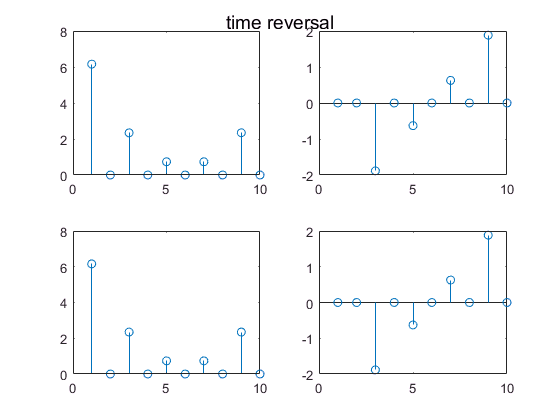

figure
x1 = [0.59 ,0.95 ,0.95 ,0.59 ,0.00 ,0.59 ,0.95 ,0.95 ,0.59 ,0.00];
x2=circshift(x1,-10);
y1=fft(x1);
y2=fft(x2);
y3=circshift(y1,-10);
suptitle('time reversal');
subplot(2,2,1);
stem(abs(y2));
subplot(2,2,2);
stem(angle(y2));
subplot(2,2,3);
stem(abs(y3));
subplot(2,2,4);
stem(angle(y3));

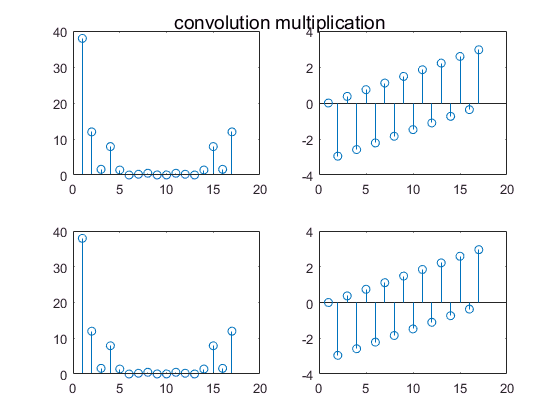


figure
x1 = [0.59 ,0.95 ,0.95 ,0.59 ,0.00 ,0.59 ,0.95 ,0.95 ,0.59 ,0.00];
x5=[zeros(1,5),x1];
x10=[zeros(1,3),x1];
y1=fft(x1,17);
y2=fft(x2,17);
x3=conv(x1,x2);
y3=fft(x3,17);
y4=y1.*y2;
suptitle('convolution multiplication');
subplot(2,2,1);
stem(abs(y3));
subplot(2,2,2);
stem(angle(y3));
subplot(2,2,3);
stem(abs(y4));
subplot(2,2,4);
stem(angle(y4));

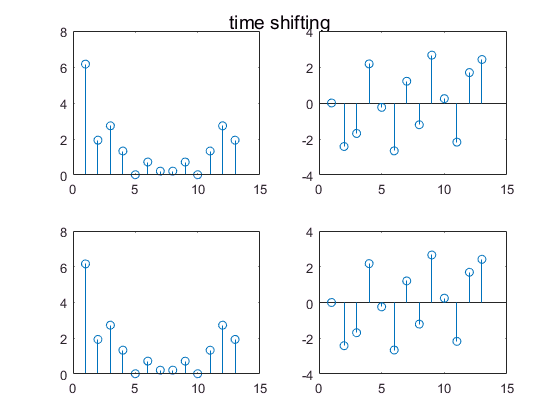


figure
x1 = [0.59 ,0.95 ,0.95 ,0.59 ,0.00 ,0.59 ,0.95 ,0.95 ,0.59 ,0.00];
x5=[zeros(1,5),x1];
x10=[zeros(1,3),x1];
t=0:12;
x7=circshift(x10,-2);
y1=fft(x10,13);
y2=fft(x7,13);
y3=(exp(2.*j.*2.*pi.*t/13)).*y1;
suptitle('time shifting');
subplot(2,2,1);
stem(abs(y3));
subplot(2,2,2);
stem(angle(y3));
subplot(2,2,3);
stem(abs(y2));
subplot(2,2,4);
stem(angle(y2));


figure
x1 = [0.59 ,0.95 ,0.95 ,0.59 ,0.00 ,0.59 ,0.95 ,0.95 ,0.59 ,0.00];
x5=[zeros(1,5),x1];
x10=[zeros(1,3),x1];
a1=abs(x1);
sum(a1.*a1)

ans = 5.0024

a2=abs(fft(x1));
a3=sum(a2.*a2);
a3/10

ans = 5.0024

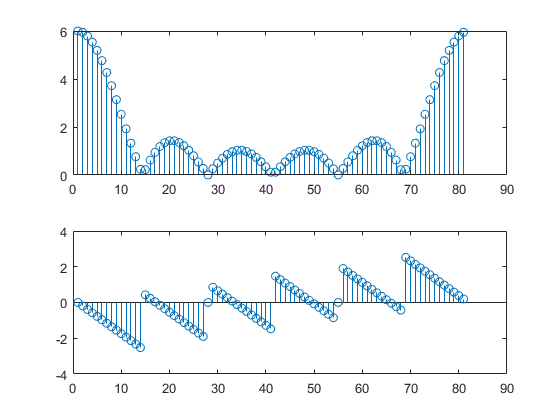

figure
t=0:.1:8;
x1=rectangularPulse(t);
subplot(2,1,1);
stem(abs(fft(x1)));
subplot(2,1,2);
stem(angle(fft(x1)));

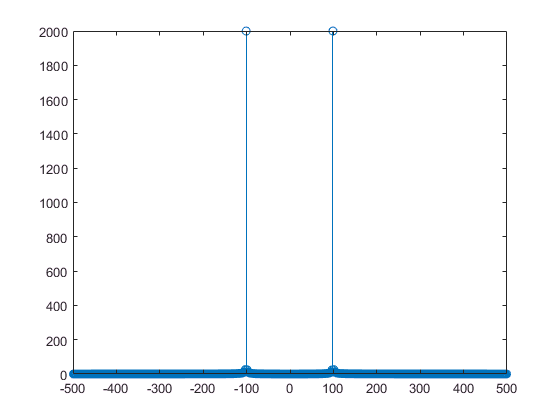

figure
t=0:1/8000:0.5;
x=sin(2*pi*100*t);
y=fftshift(fft(x));
f=-(8000/2):8000/length(y):(8000/2)-1;
figure
stem(f,abs(y));
xlim([-500 500]);

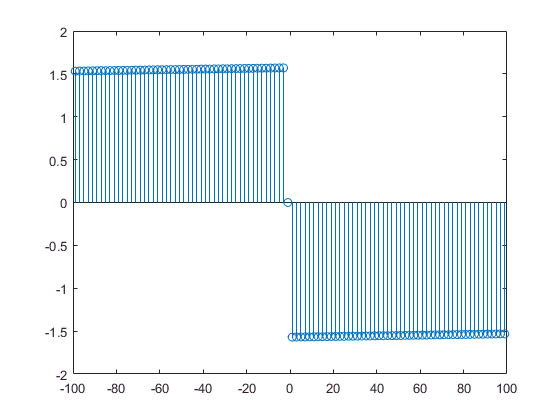

figure
stem(f,angle(y));
xlim([-100 100]);

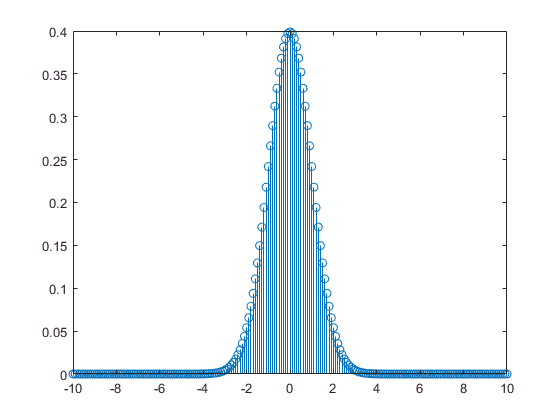



figure
x = -10:.1:10;
y =((1/(2.*pi)).^(1/2)).*gaussmf(x,[1 0]);
stem(x,y);

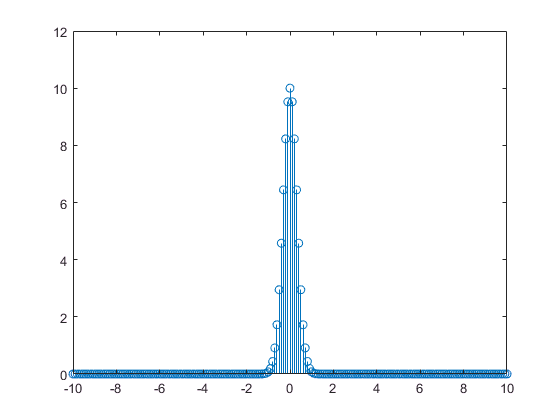

figure
y1=fftshift(fft(y));
stem(x,abs(y1));

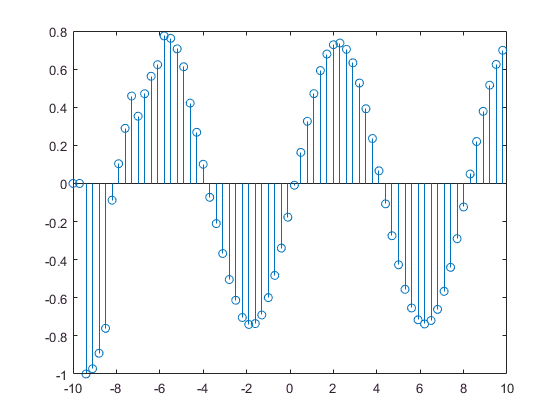

figure
n=-10:0.3:10;
a=[1,0,0,0,0.5];
b=[0,0,1];
x=sin(pi.*n/4);
y=filter(b,a,x);
stem(n,y);

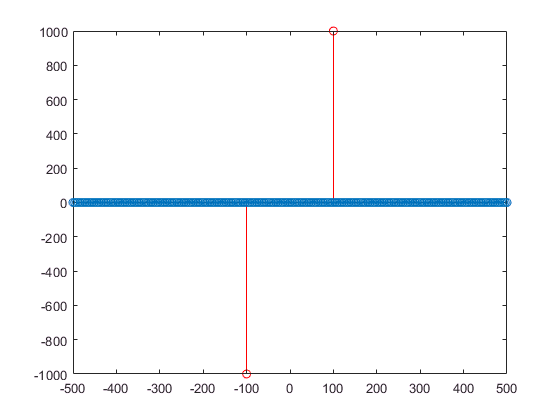

figure
t=-1000/8000:1/8000:(1000/8000)-0.000125;
x1=sin(pi.*t*200);
y=(fftshift(fft(x1)));
f=-(8000/2):8000/length(y):(8000/2)-1;
stem(f,imag(y),'r');
hold on
stem(f,real(y));
xlim([-500 500])

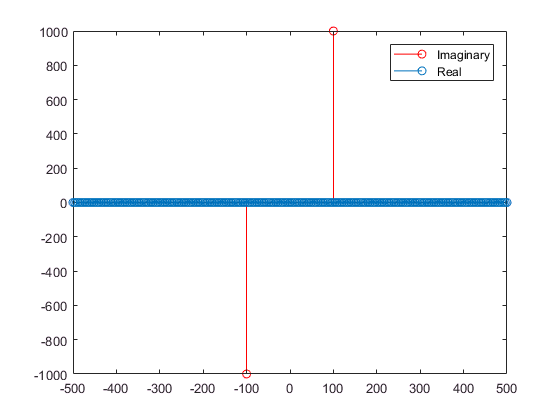

figure
t=-1000/8000:1/8000:(1000/8000)-0.000125;
x1=sin(pi.*t*200);
y=(fftshift(fft(x1)));
f=-(8000/2):8000/length(y):(8000/2)-1;
stem(f,imag(y),'r');
hold on
stem(f,real(y));
xlim([-500 500]);
legend('Imaginary','Real')

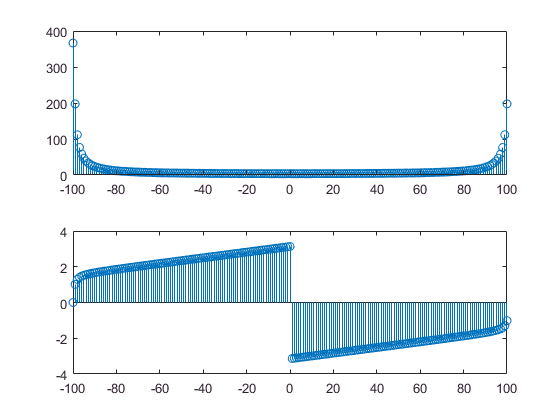

figure
t=-100:100;
x1=exp(0.02.*t);
subplot(2,1,1);
stem(t,abs(fft(x1)));

subplot(2,1,2);
stem(t,angle(fft(x1)));

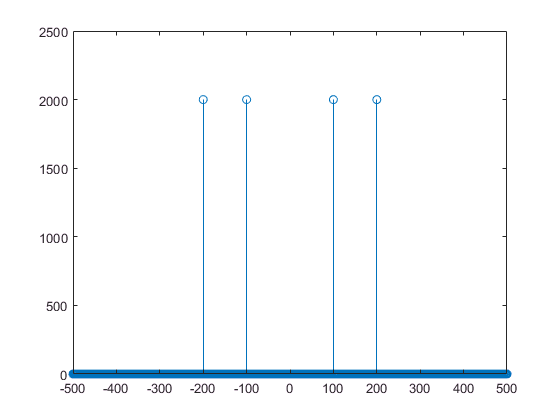

figure
t=0:1/8000:(0.5-1/8000);
x1=sin(2.*pi*200*t)+sin(2.*pi*100*t);
y=(fftshift(fft(x1)));
f=-(8000/2):8000/length(y):(8000/2)-1;
stem(f,abs(y));
xlim([-500 500]);